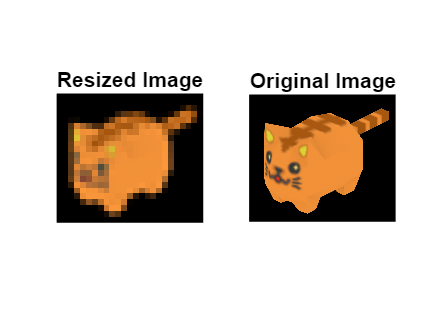

clear;
clc;
close all;

% Load image
image = im2double(imread("images/torsten.png"));

% Get original size
originalSize = size(image);  
imScalar = 30; 

% Compute new size
sizeRatio = round(originalSize(1,[1,2]) / imScalar);

% Resize image down
sizedImage = imresize(image, sizeRatio, 'bicubic');

% Display original vs resized down
figure;
subplot(1,2,1); imshow(sizedImage); title('Resized Image');
subplot(1,2,2); imshow(image); title('Original Image');

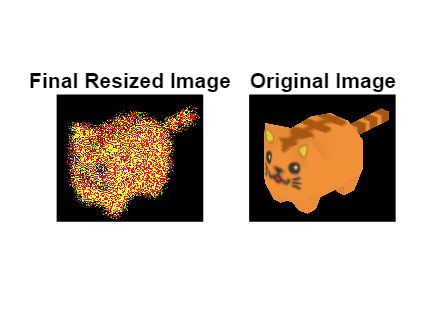


% Resize the image back up
sizedImage = imresize(sizedImage, imScalar, 'bicubic');

% Dithering
sizedImage = cat(3, double(dither(sizedImage(:,:,1))), double(dither(sizedImage(:,:,2))), double(dither(sizedImage(:,:,3))));
imDither = cat(3, double(dither(image(:,:,1))), double(dither(image(:,:,2))), double(dither(image(:,:,3))));

% Ensure it matches the original size
[rows, cols, ~] = size(sizedImage);  % Get the current size
rowsToCrop = max(0, rows - originalSize(1));  
colsToCrop = max(0, cols - originalSize(2));  
sizedImage = sizedImage(1:originalSize(1), 1:originalSize(2), :); 

% Display resized and original
figure;
subplot(1,2,1); imshow(sizedImage); title('Final Resized Image');
subplot(1,2,2); imshow(image); title('Original Image');


% Define parameters for S-CIELAB calculation
CIED65 = [95.05, 100, 108.9];
d = 15.7;         % =40cm
ppi = 267;        % pixels per inch for Surface Pro 6
sampPerDegree = ppi * d * tan(pi/180);

% Convert to XYZ color space
imageXYZ = rgb2xyz(rgb_filter(image));
imDitherXYZ = rgb2xyz(rgb_filter(sizedImage));

% Compute S-CIELAB map
scieMap = scielab(sampPerDegree, imageXYZ, imDitherXYZ, CIED65, 'xyz');

Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


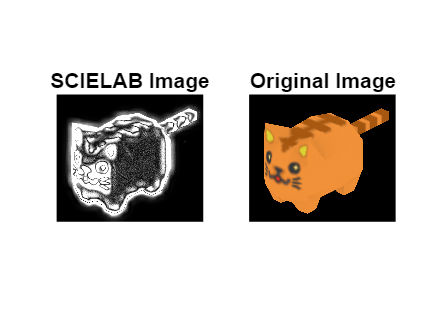


% Display S-CIELAB map
figure;
subplot(1,2,1); imshow(scieMap); title('SCIELAB Image');
subplot(1,2,2); imshow(image); title('Original Image');


% Signal-to-Noise Ratio (SNR)
disp("SNR (Resized Image): " + snr(image, image - sizedImage));

SNR (Resized Image): 2.2946


disp("SNR (Dithered Image): " + snr(image, image - imDither));

SNR (Dithered Image): 3.3145


disp("SNR (SCIELAB Image): " + snr(image, image - scieMap));

SNR (SCIELAB Image): -3.9823
